# **estimate_R**

**estimate_R** calculates the reproduction number of an epidemics. It is MATLAB translation of R function estimate_R from package [EpiEstim](https://cran.r-project.org/web/packages/EpiEstim/index.html),  ver 2.2-3. In the translation, the original structure of the functions and their names was preserved as far as possible, so that the [EpiEstim reference manual](https://cran.r-project.org/web/packages/EpiEstim/EpiEstim.pdf) can be used (A.Cori et al., Package EpiEstim)

Three methods are currently supported: 'parametric_si',  'non-parametric_s' and 'uncertain_s'.

**NOTE 1**: Double-quoted strings in R must be changed to a MATLAB column. For example: "parametric_si" should be used as "parammetric_si.

**NOTE2**: Some new options have been added to the chart function  (for details see  folder @estimate_R / plot.m). In particular options for incidence, R, and serial interval plot are controlled by **options **class. Some new properties are added: *plot_type*, *title*, *extend_title. *Plot types for incidence plot and serial interval plot include '*line'*, '*bar'*, '*stairs','scatter' and for SI plot also 'area'.*

**NOTE 3**: Option *wind_len *is added to *make_config* function to set sliding window size (see Example 4)

**NOTE4**: Incidence rate (obj.IR) and attack rate (obj.AR) are calculated if user provide population. IR can then be add to the plot with plot with plot(__,'what',['IR',...],...)

For a detailed description of the algorithms see:

Anne Cori, Neil M. Ferguson, Christophe Fraser, Simon Cauchemez , A New Framework and Software to Estimate Time-Varying Reproduction Numbers During Epidemics, *American Journal of Epidemiology*, Volume 178, Issue 9, 1 November 2013, Pages 1505–1512, [https://doi.org/10.1093/aje/kwt133](https://doi.org/10.1093/aje/kwt133)

R.N. Thompson, J.E. Stockwin, R.D. van Gaalen, J.A. Polonsky, Z.N. Kamvar, P.A. Demarsh, E. Dahlqwist, S. Li, E. Miguel, T. Jombart, J. Lessler, S. Cauchemez, A. Cori, Improved inference of time-varying reproduction numbers during infectious disease outbreaks, *Epidemics*, Volume 29, 2019, [https://doi.org/10.1016/j.epidem.2019.100356.](https://doi.org/10.1016/j.epidem.2019.100356)

## Example 1

Covid-19 data for Slovenia from 1.june.2020 onward.

addpath(genpath('mEpiTools'))
addpath(genpath('mR0'))
clear all

% data for new wave of Covid-19 in Slovenia
incid.I = [......
2	2	0	2	5	1	0   ...
1	2	0	2	2	3	2   ...
3	4	8	2	6	1	1   ...
13	7	6	11	14	9	4   ...
14	13	21	16	30	21	16	...
23	24	13	17	34	14	8	...
10	19	19  19  24   6  7   ...
24  29  27  19  14  16  5   ...
14  14  24  17  15   9  1   ...
9   18  15
];
incid.start_date =  [2020,6,1];
incid.population = findCountry('Slovenia').population;

% use default 7-days window length
config = make_config('mean_si',4.7,'std_si',2.9);
res    = estimate_R(incid,'parametric_si',config);
fprintf('R = %g (CI %g - %g)  IR = %d   AR = %d\n',...
    res.mean_posterior(end),...
    res.quantile_005_posterior(end),...
    res.quantile_095_posterior(end),...
    round(res.IR(end),0),...
    round(res.AR(end),0))

R = 0.840126 (CI 0.696066 - 0.995418)  IR = 4   AR = 36


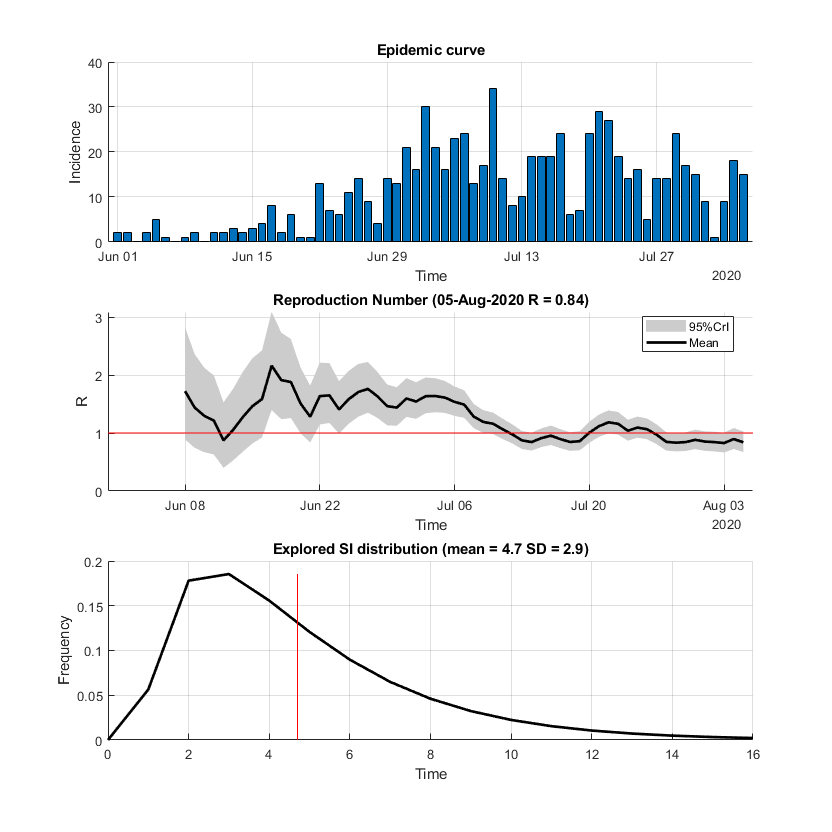

%close all
plot(res,'what','all','options_I',options('plot_type','bar'));

## Example 2

Monitoring effect of goverment measures

- No measures

- Prohibition of gathering in public places over 500people

- 14-day quarantine for people coming from crisis areas

- Prohibition of gathering in public places over 50 people

- Prohibition of gathering in public places over 10 people.

T = length(incid.I);
t_start = [2 15 19 30 39];
t_end   = [14 18 29 38 T];

config = make_config('mean_si',4.7,'std_si',2.9,...
    't_start',t_start,'t_end',t_end');
out    = estimate_R(incid,'parametric_si',config);
fprintf('R = %g (CI %g - %g)\n',...
    out.mean_posterior(end),...
    out.quantile_005_posterior(end),...
    out.quantile_095_posterior(end))

R = 0.936706 (CI 0.86512 - 1.01067)


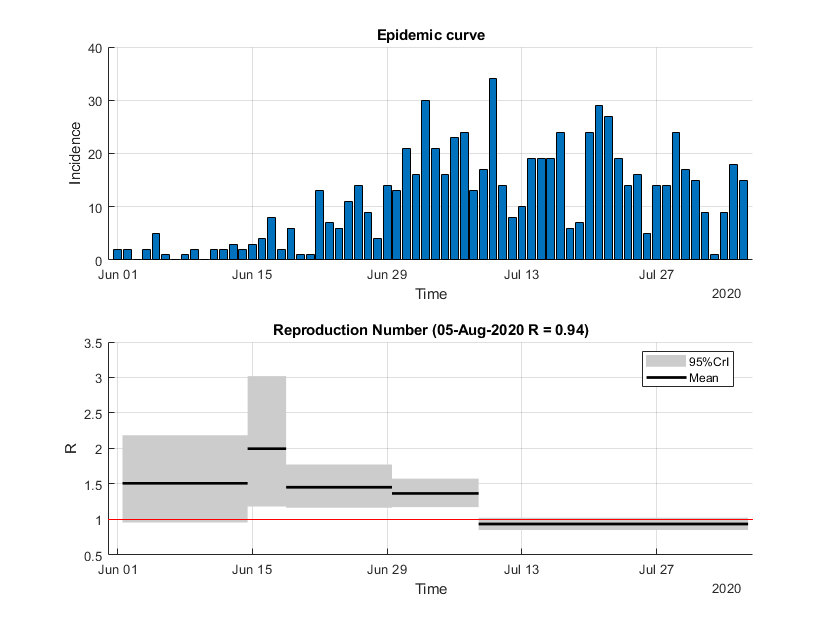


plot(out,'what',['incid','R']);

## Example 3

Demonstration of various plot options

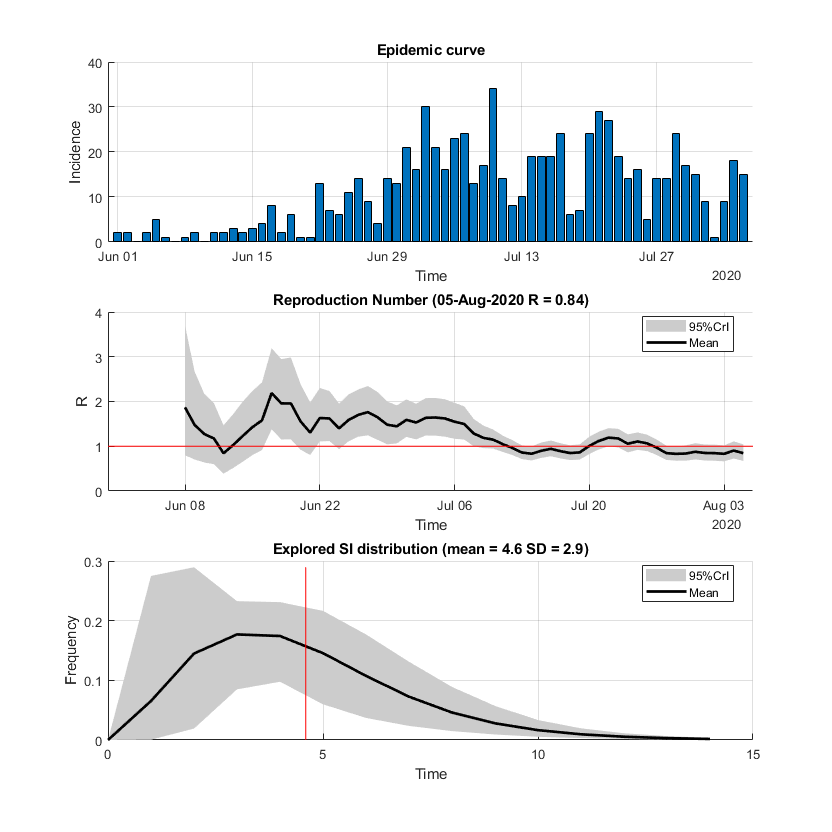

config = make_config(...
    'mean_si', 4.6, 'std_mean_si', 1,...
    'min_mean_si', 1, 'max_mean_si', 6.5,...
    'std_si' ,2.9, 'std_std_si', 0.5,...
    'min_std_si' , 0.5, 'max_std_si', 2.5);
res = estimate_R(incid,'uncertain_si',config);
plot(res,'opt_SI',options('plot_type','area'))

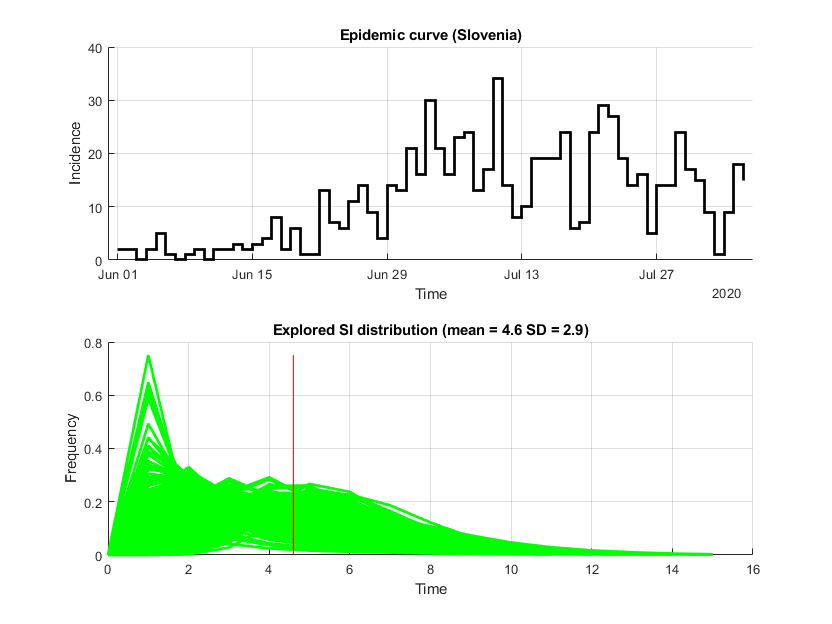

plot(res,'what',['incid','SI'],'opt_I',options(...
    'title','Epidemic curve (Slovenia)',...
    'plot_type','stairs'))

## Example 4

Import data, use 14-days window length and 'uncertain_si' methosd.

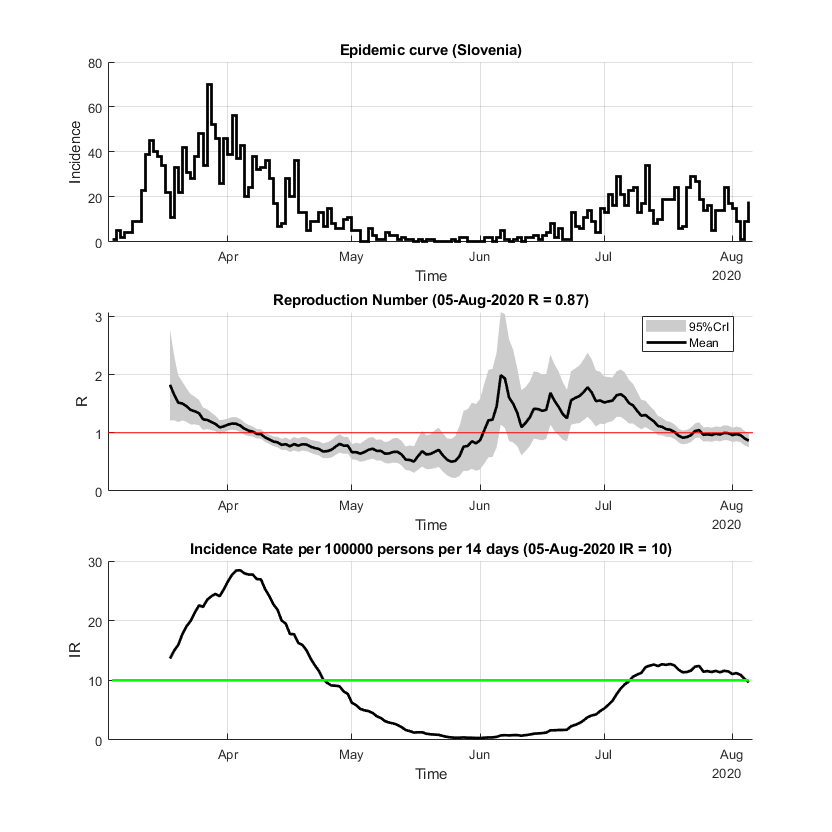

slo = importData('Slovenia');
config = make_config( ...
    'wind_len',14,...
    'mean_si', 4.6, 'std_mean_si', 1,...
    'min_mean_si', 1, 'max_mean_si', 6.5,...
    'std_si' ,2.9, 'std_std_si', 0.5,...
    'min_std_si' , 0.5, 'max_std_si', 2.5);
res = estimate_R(slo,'uncertain_si',config);
plot(res,'what',['incid','R','IR'],'opt_I',options(...
    'title','Epidemic curve (Slovenia)',...
    'plot_type','stairs'))

fprintf('R = %g (CI %g - %g)  IR = %d   AR = %d\n',...
    res.mean_posterior(end),...
    res.quantile_005_posterior(end),...
    res.quantile_095_posterior(end),...
    round(res.IR(end),0),...
    round(res.AR(end),0))

R = 0.866779 (CI 0.766956 - 0.970926)  IR = 10   AR = 106
